# Informe de Laboratorio 2

## Pregunta 1

Realice una síntesis, de las decisiones tomadas en el anterior laboratorio

Respuesta:

1. Gráfico del ajuste del programa en Simulink con la incorporación de los parámetros obtenidos de la caracterización del sensor de nivel

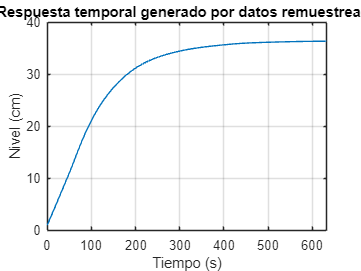

Tiempo=[0:1:63257]';
Nivel_suave=smoothdata(Nivel_sensor,'lowess');
%% Remuestro el función de 63258 datos da 36.
Nivel_indice=round(linspace(1,numel(Nivel_suave),600));
Tiempo_indice=round(linspace(1,numel(Tiempo),600));
Nivel_remuestreado=Nivel_suave(Nivel_indice);
%%% función resultante
Tiempo_remuestreado=Tiempo(Tiempo_indice)/(100);
f_exp=plot(Tiempo_remuestreado,Nivel_remuestreado);
title('Respuesta temporal generado por datos remuestreada');
xlabel('Tiempo (s)');
ylabel('Nivel (cm)');
grid on;

2. Función de transferencia continua seleccionada, recordando la razón y los gráficos comparativos de soporte para la decisión.

La función de transferencia continua seleccionada fue la aproximada con padé. 

s=tf('s');
%Declara constantes
Tiempo_muerto=21.2;
retraso=exp(-Tiempo_muerto*s);
Nivel_satura=36.4;
Nivel_63=36.4*0.63;
tiempo_63=94.97;
a=1/tiempo_63;
K=Nivel_satura*a;
%Crea función de transferencia

G=K/(s+a); % Función de transferencia experimental
G1=G*retraso; % Función de transferencia retrasada.
G_pade=pade(G1,1) % Función de transferencia con padé.

G_pade =
 
     -0.3833 s + 0.03616
  --------------------------
  s^2 + 0.1049 s + 0.0009934
 
Continuous-time transfer function.
Model Properties


3. Respuesta frecuencial por medio de un Diagrama de Bode y su respectivo análisis.

El diagrama de Bode del sistema es de fase no mínima, se necesita utilizar un diagrama de Nyquist para analizar la estabilidad del sistemas, ademas tiene un margen de ganancia de -11.3 dB y un margen de fase de -60.8°.

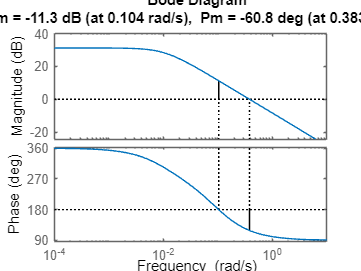

margin(G_pade) % Diagrama de bode del sistema y sus margenes.

4. Función de transferencia discreta obtenida, recordando las razones para su obtención.

Tiempo_muestreo=1;
Gz1=c2d(G_pade,Tiempo_muestreo,'zoh') % Función discretizada

Gz1 =
 
    -0.3463 z + 0.3807
  ----------------------
  z^2 - 1.899 z + 0.9004
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


## Pregunta 2

Reporte en 4 gráficos comparativos superpuestos (para lo cual es necesario revisar la escala de los ejes), la respuesta a la señal impulso, escalón, rampa y sinusoidal obtenidas tanto con las funciones en tiempo continuo, como a la planta real, realizando un análisis sintético de los resultados logrados.

Respuesta:

En simulink se hizo el siguiente diagrama:

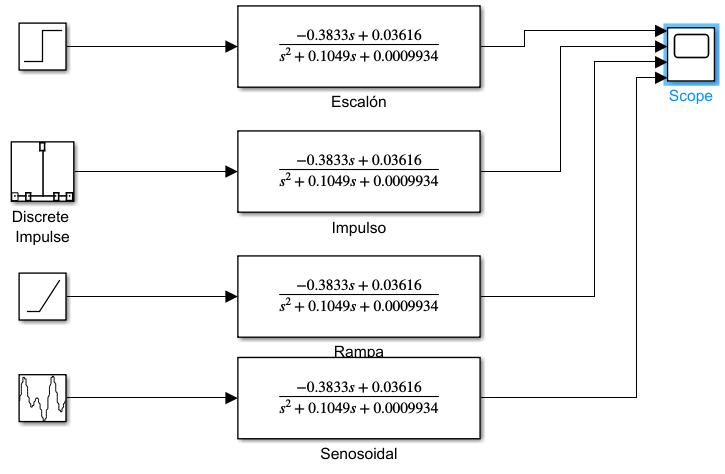

Finalmente se obtiene la salida:

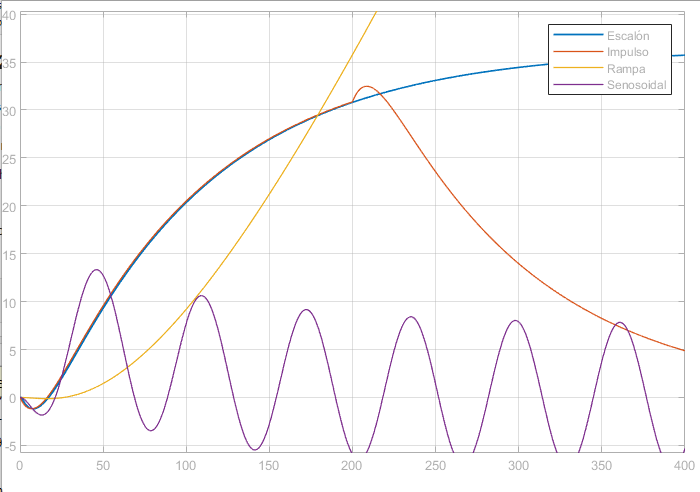

Las respuestas impulso y escalón comparten cierta tendencia hasta t=200, por otro lado el sistema siempre esta creciendo con la respuesta a una rampa y decreciendo con la respuesta tipo senosoidal. 

## Pregunta 3

Complemente la tabla comparativa que se observa a continuación tras la incorporación de las diferentes constantes tanto en el PID que provee la planta.

**Respuesta**:

**LUGAR DE LAS RAÍCES **

Se utiliza la herramienta sisotool para mover los polos dado su lugar geométrico. La respuesta es la siguiente:

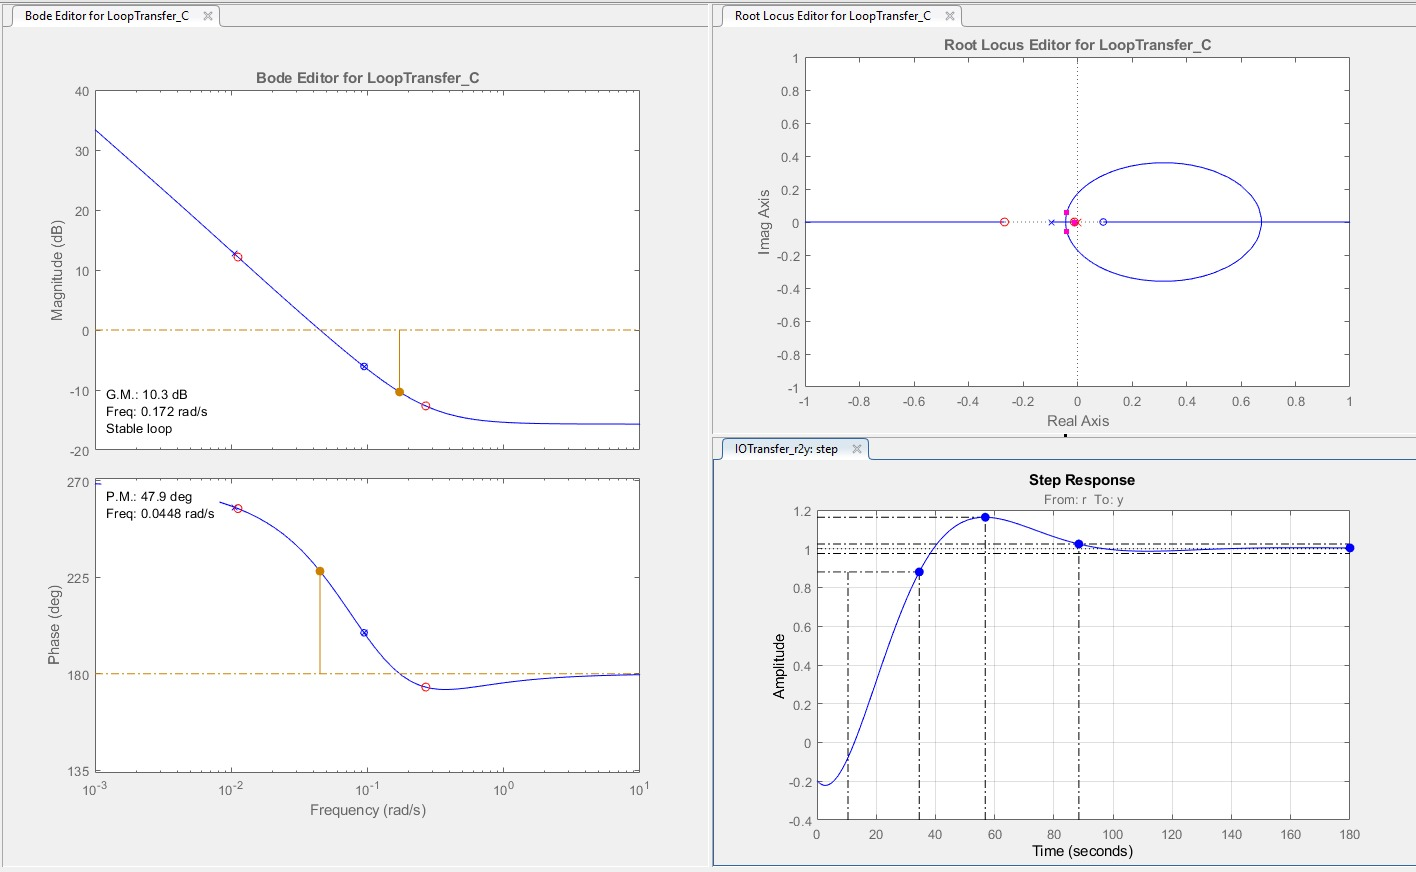

Las anteriores gráficas genera un compensador (PID).

Finalmente obtenemos las constantes con el siguiente código:

%PID Obtenido con siso tool (Lugar raices) 
% Definir la función de transferencia del compensador
compensador =(0.42891*(s+0.2678)*(s+0.0112))/s;

% Extraer la función de transferencia del compensador
[num, den] = tfdata(compensador, 'v');

% Obtener las constantes del controlador PID
Kp = num(2);  % Coeficiente del término proporcional
Ki = num(3);  % Coeficiente del término integral
Kd = num(1);       % No hay término derivativo en este caso

**PID TUNER**

Utilizando el PID tuner se encuentra las constantes de PID de forma automática.

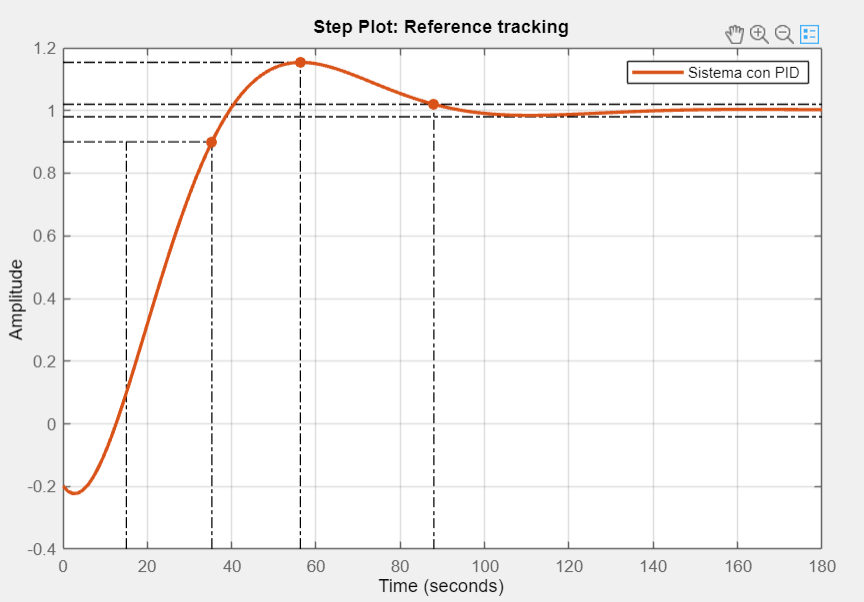 

Con los siguientes paramétros:

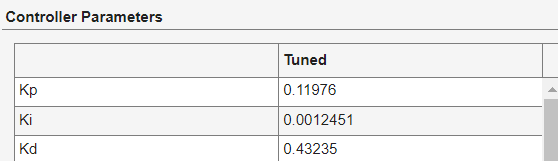

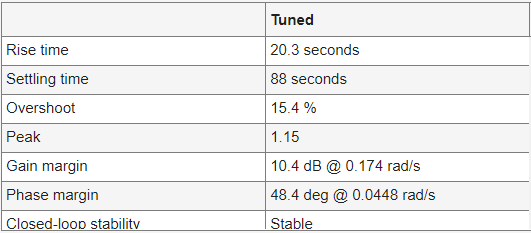

**ZIEGLER-NICHOLS**

Utilizando simulink se encontró las constante del pid, como muestra la siguiente figura. Se varia la ganacia hasta lograr una respuesta oscilatoria estable y se hallan los valores de Kp, Ti y Td siguiendo el metodo. El resulado obtenido se escalo para obtener constantes proporcionales al sistema. 

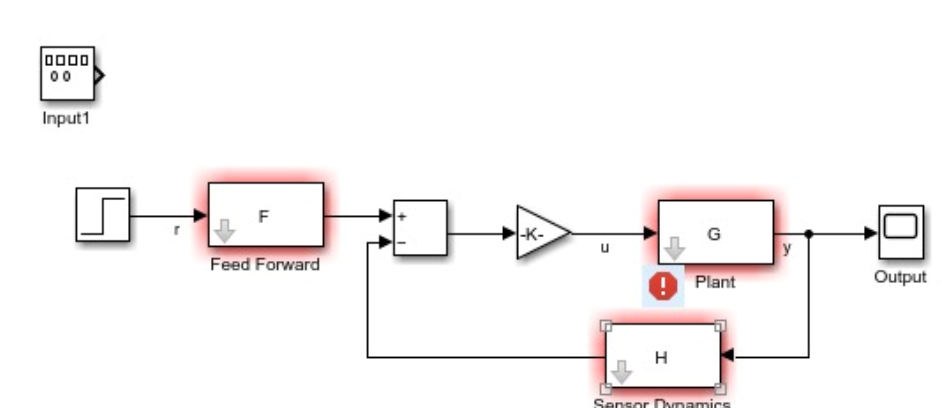

Tabla:

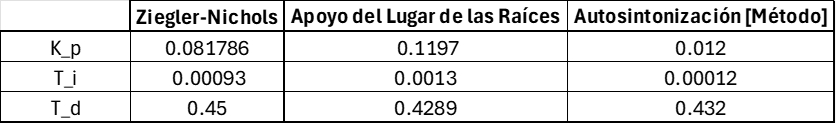

## Pregunta 4

Complemente la tabla comparativa que se observa a continuación y genere un análisis de lo obtenido, para finalizar con una selección argumentada de la mejor combinatoria:

**Respuesta**:

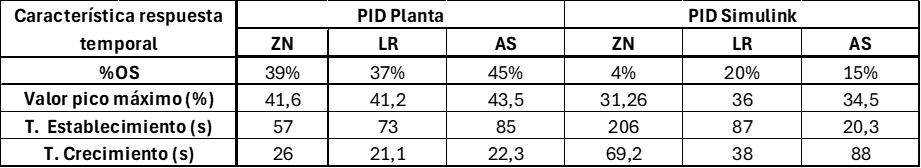

De la tabla anterior notamos que el overshoot ronda el 40% puesto que todos las valores fueron con una referencia del 30%. Tambien el modelo simulink que más se acerca al comportamiento de la planta es el obtenido por PID tuning.

## Pregunta 5

Reporte el mismo numeral 2 para la función de transferencia discreta.

Se realiza en simulink el siguiente diagramwa

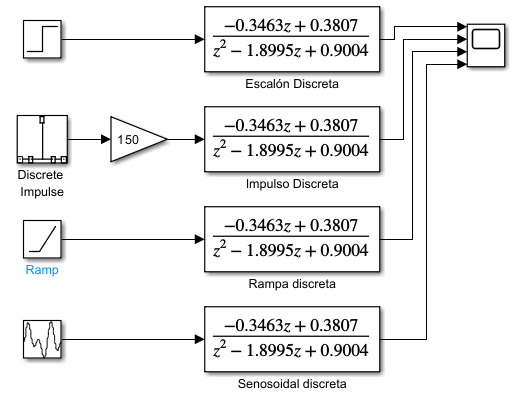

y se obtiene la respuesta:

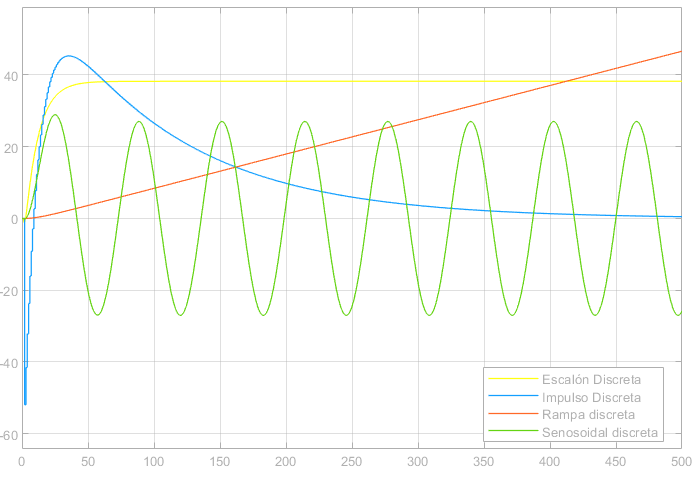

## Pregunta 6

Reporte en tablas similares a las comentadas en los numerales 3 y 4 el resultado de las acciones adelantadas para un control discreto, omitiendo en la tabla del numeral 4 la prueba desde el control propio de la planta. Genere un análisis de los resultados y seleccione la opción que muestre mejor desempeño.

**Respuesta**:

Puesto que las constantes del PID serán parecidas de forma continua o discreta, se realiza una comparación entre 3 tipos de controles. ZN, LR, y AS. 

%Zieger Nichols method

Kp_z = 0.081786;
Ki_z = 0.00093;
Kd_z = 0.45;

%Lugar raices method

Kp_l = 0.1197;
Ki_l = 0.0013;
Kd_l = 0.4289;

%PID Tuner method

Kp_t = 0.012;
Ki_t = 0.00012;
Kd_t = 0.432;
Planta = tf([-0.3833 0.0616],[1 0.1049 0.000994]);

Plt_Dis = c2d(Planta,1,"zoh") %tiempo de discretizacion 1s

Plt_Dis =
 
    -0.3341 z + 0.3925
  ----------------------
  z^2 - 1.899 z + 0.9004
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


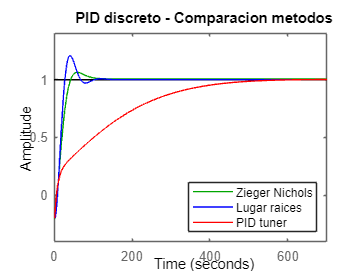

PID_z = Kp_z + Ki_z/s + Kd_z*s;
PID_l = Kp_l + Ki_l/s + Kd_l*s;
PID_t = Kp_t + Ki_t/s + Kd_t*s;

Sys_z = c2d(feedback(PID_z*Planta,1),1,"zoh");
Sys_l = c2d(feedback(PID_l*Planta,1),1,"zoh");
Sys_t = c2d(feedback(PID_t*Planta,1),1,"zoh");

figure;
hold on
step(Sys_z,"g")
step(Sys_l,"b")
step(Sys_t,"r")
title("PID discreto - Comparacion metodos")
legend(["Zieger Nichols" "Lugar raices" "PID tuner"],"location","southeast")
hold off  

Finalmente se tabula la tabla simulada

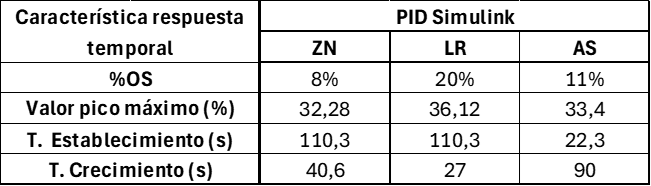

## Pregunta 7

Realice una gráfica comparativa y superpuesta entre la respuesta temporal lograda con el PID continuo implementado en Simulink y el PID discreto igualmente implementado en Simulink. Genere un análisis, seleccione la opción que muestre mejor desempeño y obtenga una conclusión preliminar.

**Respuesta**:

Se selecciona el PID obtenido con el metodo de lugar de las raices, y se compara con su analogo continuo:

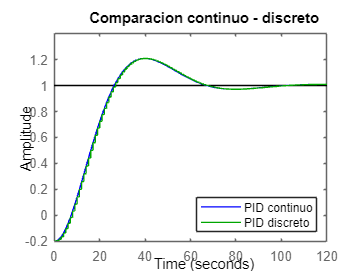

Sys_c = feedback(PID_l*Planta,1);

figure;
hold on
step(Sys_c,"b")
step(Sys_l,"g")
legend(["PID continuo" "PID discreto"],"location","southeast")
title("Comparacion continuo - discreto")
hold off  

Podemos ver como el función discreta del PID se aproxima en gran medida al PID continuo.

## Pregunta 8

Reporte el Diagrama de Bode y de Nyquist obtenidos para la función de transferencia continua seleccionada, generando un análisis y logrando conclusiones al respecto. 

Respuesta:

Diagrama de bode:

margin(G_pade)

Del diagrama anterior podemos ver que la fase empieza en 360°, esto es un indicador de que el sistema es de fase NO mínima y el diagrama de bode NO es suficiente para analizar el sistema. 

Diagrama de Nyquist

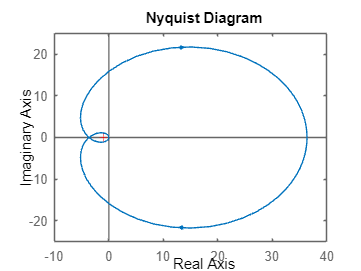

nyquist(G_pade)

Recordemos que el diagrama de Nyquist análiza los polos de la función de transferencia en bucle cerrado a partir de la función de transferencia en bucle abierto. 

En general se puede decir que hay 3 caminos de Nyquist. 

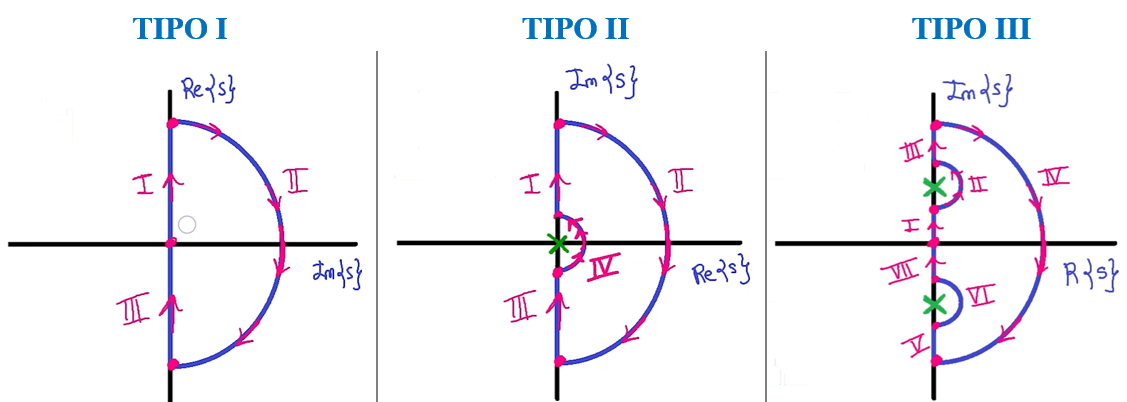

Los caminos se eligen en función de los polos y los ceros en bucle abierto. 

En este caso tenemos un camino tipo 1, puesto dado nuesto diagrama de nyquist notamos que el polo no está en el origen. 

Dado el anterior diagrama de Nyquist, tenemos lo siguiente:

syms N P Z
%sea
Z=P+N

$$Z = N+P$$

El sistema será estable si Z=0

P es la cantidad de polos o ceros que estan "dentro del camino", en nuestro caso, no hay por lo que P=0. 

Por otro lado N, me dice la cantidad de ciclos sobre el -1. 

En nuestro caso vemos que hay 2 ciclos, un pequeño y uno grande, los dos en sentido horario, por lo que N=1+1=2. Luego,

Z=2

Z = 2

 En base a lo anterior vemos que el sistema NO es estable, por lo que se requiere aplicar un controlador. 

## Pregunta 9

Plasme el diagrama del compensador de adelanto o de retraso según la necesidad que se obtuvo a partir de la respuesta frecuencial para la función de transferencia continua seleccionada, así como la respuesta temporal a una señal escalón con su respectivo análisis y conclusiones.

**Respuesta**:

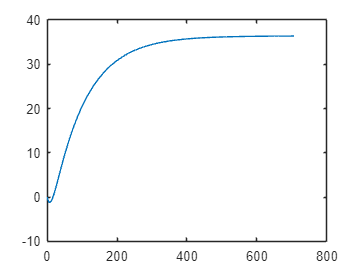

% Definir los coeficientes del numerador (b) y del denominador (a) de la función de transferencia
b = [-0.3833  0.03616]; % Por ejemplo, para una función de transferencia 2s + 3
a = [1 0.1049 0.0009934]; % Por ejemplo, para un denominador s^2 + 0.4s + 1

% Convertir la función de transferencia a espacio de estados
[A,B,C,D] = tf2ss(b,a);
EspacioEsta = ss(A,B,C,D);

% A, B, C, D son las matrices del sistema en espacio de estados
[y,t]=step(EspacioEsta);
plot(t,y)

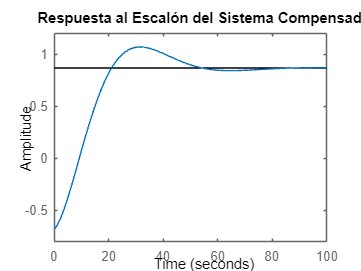


% Crear la función de transferencia
G = tf(b, a);
Comp = 1.0593 * (tf([1 0.1718], [1]));

% Conectar el compensador con la planta a lazo cerrado
sistema_compensado = feedback(Comp*G, 1);

% Analizar el sistema compensado
figure;
step(sistema_compensado);
title('Respuesta al Escalón del Sistema Compensado');

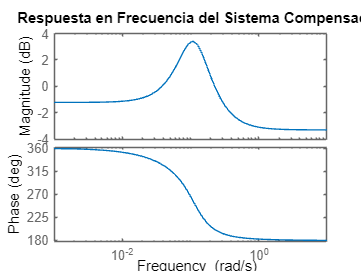

figure;
bode(sistema_compensado);
title('Respuesta en Frecuencia del Sistema Compensado');

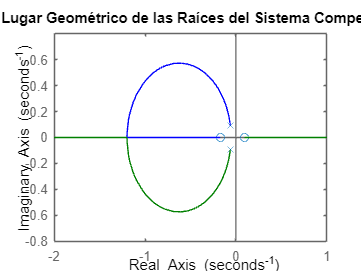


figure;
rlocus(sistema_compensado);
title('Lugar Geométrico de las Raíces del Sistema Compensado');

Para obtener C, se emplea los requerimientos establecidos por el PID de prueba en los valores As, se implemento la herramienta sisotool para poder obtener el valor y analizar el comportamiento de la función  de transferencia. Se observa que el sistema logra estabilizarse a los 20 segundos al aplicarse un step. Se observa en el bode como el compensador interactúa con la respuesta a la frecuencia. Adicionalmente se obtiene el lugar geométrico de las raíces para la función de transferencia ajustada

La siguiente imagen muestra la reebucación de polos por medio de sisotool. 

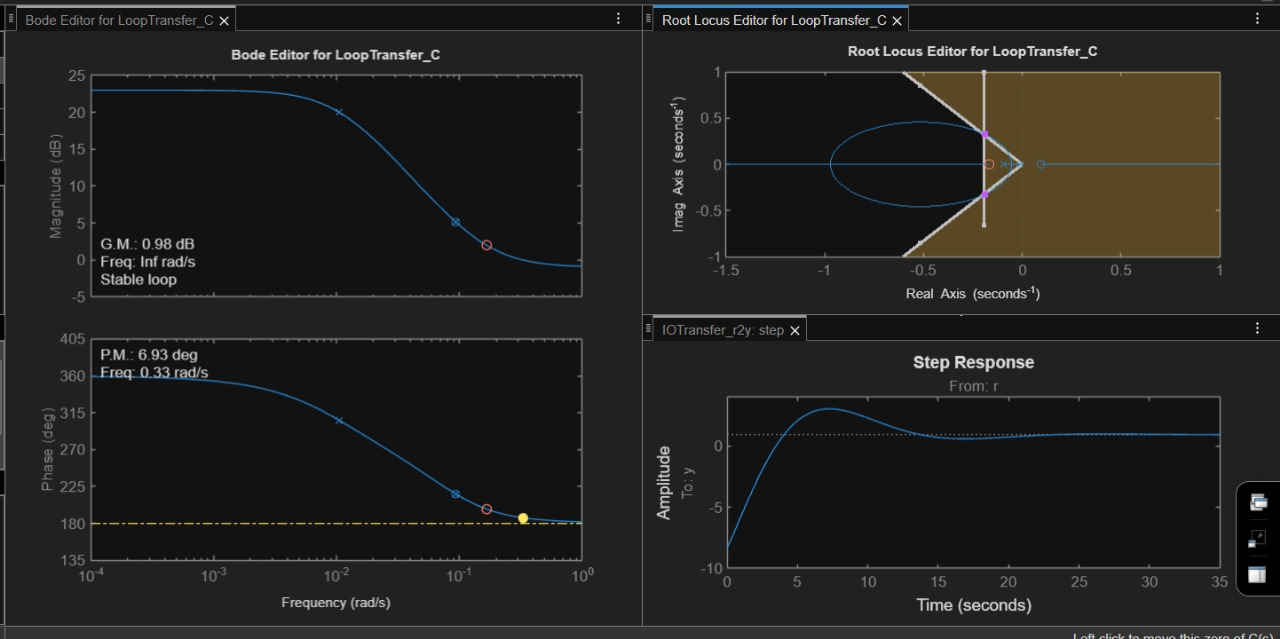

## Pregunta 10

Para el modelo en Espacio de Estados logrado, obtenga y analice la característica de controlabilidad y observabilidad del sistema.

Respuesta:

% Matriz de controlabilidad
Co = ctrb(A, B);
% Verificar si el sistema es controlable
rango_co = rank(Co);

% Matriz de observabilidad
Oo = obsv(A, C);
% Verificar si el sistema es observable
rank(A)

ans = 2

Debido a que el rango de la matriz de controlabilidad y obserbabilidad es igual al rango de la matriz de estado, el sistema es observable y controlable. 

## Pregunta 11

Posterior al análisis de controlabilidad y observabilidad de la planta, reporte el esquema del control por ubicación de polos aplicado al modelo en Espacio de Estados, la respuesta temporal arrojada al aplicar la señal escalón, la extracción de las principales características dicha respuesta temporal [%OS, VPM, Ts, Tc], un análisis de los resultados y unas conclusiones preliminares. 

Respuesta:

% Diseño del controlador
polos_deseados =[-1 -2 ];

K = place(A, B, polos_deseados);

% Comprobación de la estabilidad del sistema en lazo cerrado
Acl=A-B*K;
eigenvalues = eig(Acl);
if all(real(eigenvalues) < 0)
    disp('El sistema en lazo cerrado es estable.');
else
    disp('El sistema en lazo cerrado es inestable.');
end

El sistema en lazo cerrado es estable.


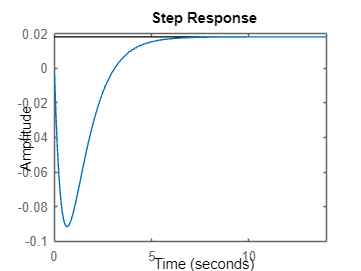

figure; 
sys55 = ss(Acl, B, C,D);
step(sys55)

## Pregunta 12

Realice una tabla similar a la del numeral 4, así como una gráfica comparativa superpuesta donde sea posible visualizar el desempeño del control PID para la función de transferencia continua, el discreto, el compensador basado en respuesta frecuencial y por medio de ubicación de polos al modelo en Espacio de Estados. Realice un análisis de los resultados y las conclusiones

**Respuesta**:

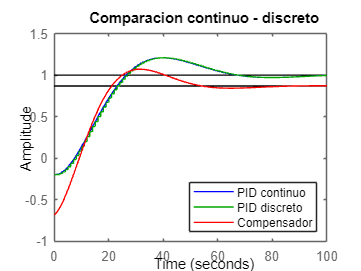

Sys_c = feedback(PID_l*Planta,1);

figure;
hold on
step(Sys_c,"b")
step(Sys_l,"g")
step(sistema_compensado,"r");
legend(["PID continuo" "PID discreto" "Compensador"],"location","southeast")
title("Comparacion continuo - discreto")
xlim([0 100 ])
hold off